# Phys 434 Lab 2

## Natalie Shen

### Collaborators: Francesca Bennet, Taylor Prewitt

clear all;
close all;
clc;

### Problem 1

#### A)

x = 6

y = 9

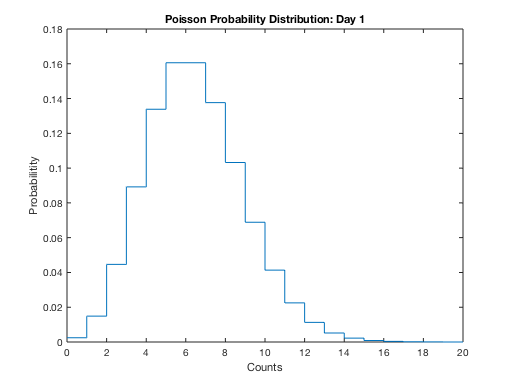

x = 0:20;
p = poisspdf(x,6);
stairs(x,p);
title("Poisson Probability Distribution: Day 1");
xlabel("Counts");
ylabel("Probabilitity");

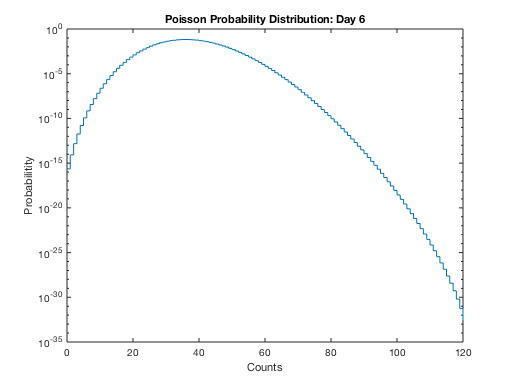



z2 = conv(p,p);
z3 = conv(p,z2);
z4 = conv(p,z3);
z5 = conv(p,z4);
z6 = conv(p,z5);
x = 0:(20 * 6);
stairs(x,z6);
title("Poisson Probability Distribution: Day 6");
xlabel("Counts");
ylabel("Probabilitity");
set(gca,'YScale','log');

#### B)

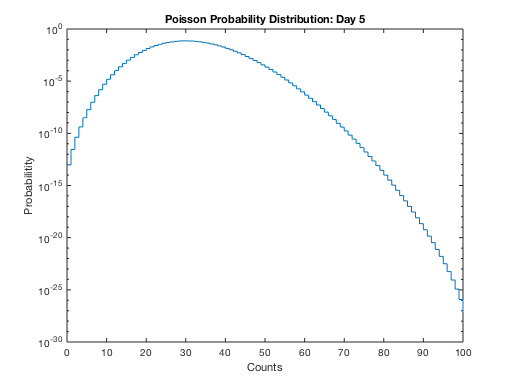

x = 0:(20 * 5);
stairs(x,z5);
title("Poisson Probability Distribution: Day 5");
xlabel("Counts");
ylabel("Probabilitity");
set(gca,'YScale','log');

#### C)

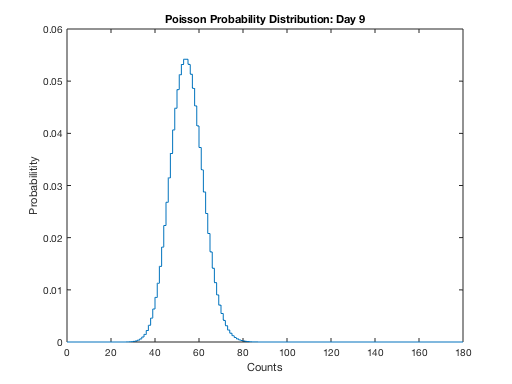

z7 = conv(p,z6);
z8 = conv(p,z7);
z9 = conv(p,z8);
z10 = conv(p,z9);
z11 = conv(p,z10);
z12 = conv(p,z11);
z13 = conv(p,z12);
z14 = conv(p,z13);
z15 = conv(p,z14);

x = 0:(20 * 9);
stairs(x,z9);
title("Poisson Probability Distribution: Day 9");
xlabel("Counts");
ylabel("Probabilitity");

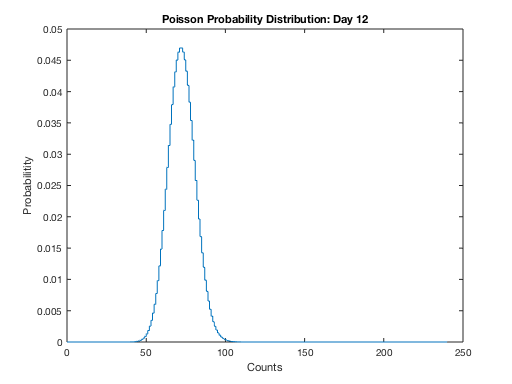


x = 0:(20 * 12);
stairs(x,z12);
title("Poisson Probability Distribution: Day 12");
xlabel("Counts");
ylabel("Probabilitity");

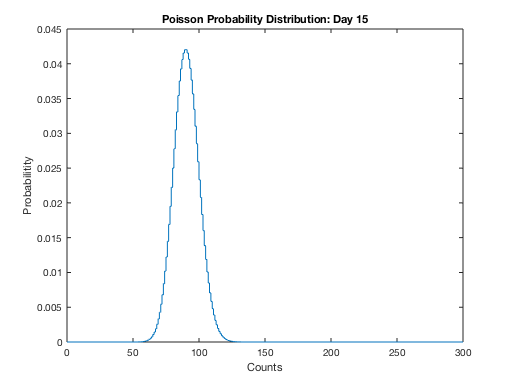


x = 0:(20 * 15);
stairs(x,z15);
title("Poisson Probability Distribution: Day 15");
xlabel("Counts");
ylabel("Probabilitity");

#### D)

N = 10;
Y = 7;
x = 6;

%70 with average of 60

prob = 1-poisscdf(N * Y,x * N)

prob = 0.0902


s = abs(norminv(prob,0,1))

s = 1.3396

### Problem 2

#### A)

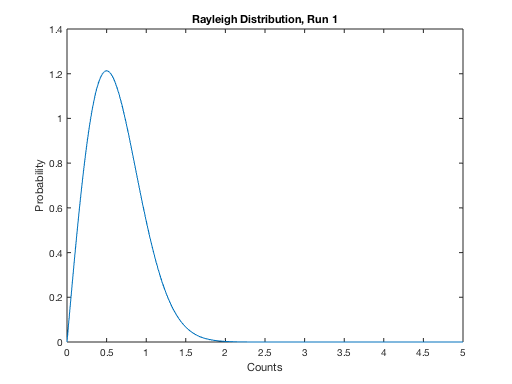

x=0:.01:10;
r1=raylpdf(x,.5);
plot(x,r1)
title("Rayleigh Distribution, Run 1");
xlabel("Counts");
ylabel("Probability");
xlim([0 5]);

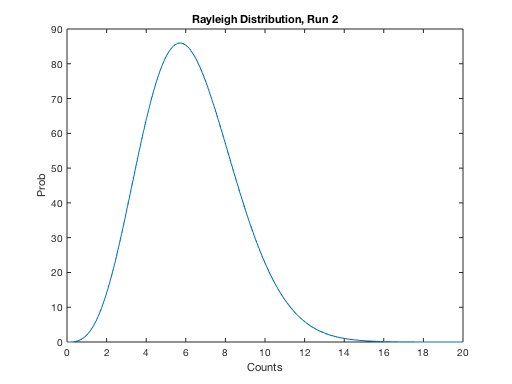


r2=conv(r1,r1);
l = length(r2)-1;
x=0:100/l:100;
plot(x,r2)
title("Rayleigh Distribution, Run 2");
xlabel("Counts");
ylabel("Prob");
xlim([0 20]);

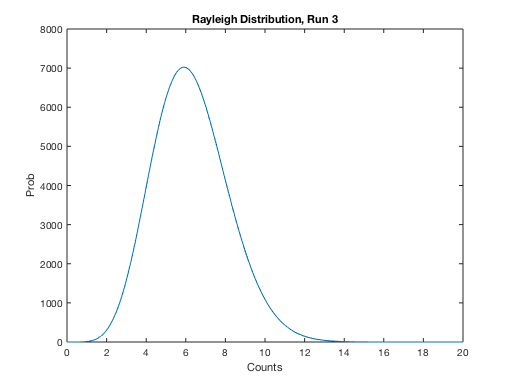


r3=conv(r1,r2);
l = length(r3)-1;
x=0:100/l:100;
plot(x,r3)
title("Rayleigh Distribution, Run 3");
xlabel("Counts");
ylabel("Prob");
xlim([0 20]);

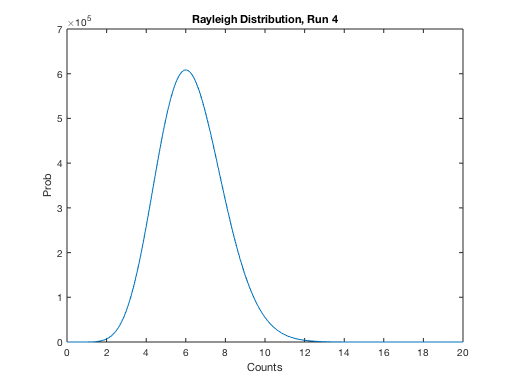


r4=conv(r1,r3);
l = length(r4)-1;
x=0:100/l:100;
plot(x,r4)
title("Rayleigh Distribution, Run 4");
xlabel("Counts");
ylabel("Prob");
xlim([0 20]);

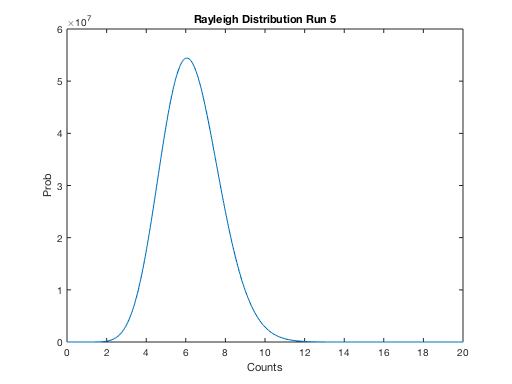


r5=conv(r1,r4);
l = length(r5)-1;
x=0:100/l:100;
plot(x,r5)
title("Rayleigh Distribution Run 5");
xlabel("Counts");
ylabel("Prob");
xlim([0 20]);

#### B)

The graph becomes more and mroe symmetric per run/interval with run 5 nearly resembling a guassian distribution. Possibly a few more runs would result in a near identical guassian distribution shape.

### Problem 3

#### Version 1

#### A)

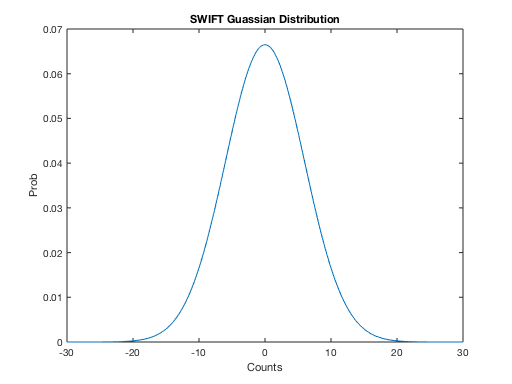

%X = 6, Y = 15
d = makedist('Normal',0,6);
x = linspace(-30,30,1000);
plot(x, pdf(d,x))
title("SWIFT Guassian Distribution");
xlabel("Counts");
ylabel("Prob");


a = normcdf(15,0,6);
sigma = abs(1-a)

sigma = 0.0062

#### Version 2

#### B)

Most likely be a guassian distribution as submitting the 10k pixels into a guassian distribution will cause their probabilities to be the same.

#### C)

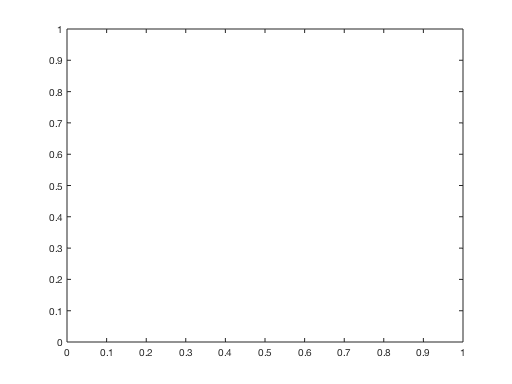

Y = pdf("Normal",x,5)*1000;
plot(x,Y);

### Problem 4

#### A)